# Ship Tracking Using AIS Signals

This example shows how to track ships by processing automatic identification system (AIS) signals. You can use previously captured signals or receive signals in real time using an RTL-SDR radio, an ADALM-PLUTO radio or a USRP™ Radio. You can also show the tracked ships on a map using the Mapping Toolbox™. 

## Required Hardware and Software

By default, this example runs using previously captured signals. Optionally, you can receive signals over-the-air. For this, you also need one of the following:

- RTL-SDR radio and [Communications Toolbox Support Package for RTL-SDR Radio](https://www.mathworks.com/hardware-support/rtl-sdr.html).

- ADALM-PLUTO radio and [Communications Toolbox Support Package for ADALM-PLUTO Radio](https://www.mathworks.com/hardware-support/adalm-pluto-radio.html).

- 200-Series USRP Radio and [Communications Toolbox Support Package for USRP Radio](https://www.mathworks.com/hardware-support/usrp.html). For information on how to map an NI™ USRP device to an Ettus Research™ 200-series USRP device, see [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- 300-Series USRP Radio and [Wireless Testbench Support Package for NI USRP Radios](https://www.mathworks.com/hardware-support/ni-usrp-radios.html). For information on how to map an NI USRP device to an Ettus Research 300-series USRP device, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

## Overview

In marine transportation, vessel traffic services use AIS as a component of the marine traffic monitoring system. AIS performs these functions:

- Transmit vessel identifier, position, course, and speed.

- Receive and process specified interrogating calls.

- Operate continuously while sailing or at anchor.

AIS has these attributes:

- A transmit frequency in the range 156.025 MHz-162.025 MHz

- Gaussian frequency shift keying modulation

- A bit rate of 9600 bits/sec

- A transmit bandwidth-time product of 0.4

- A receive bandwidth-time product of 0.5

- A modulation index of 0.5

AIS transmission packets contain these fields:

- Training Sequence — 24-bit sequence of alternating zeros and ones (0101...)

- Start Flag — 8-bit sequence, 01111110

- Data — The data portion is 168 bits long in the default transmission packet

- Frame Check Sequence (FCS) — Uses the cyclic redundancy check (CRC) 16-bit polynomial to calculate the checksum

- End Flag — Identical to the start flag

- Buffer — 24 bits long to account for bit stuffing (maximum 4 bits), distance delay (14 bits), and synchronization jitter (6 bits)

This figure shows the AIS packet format

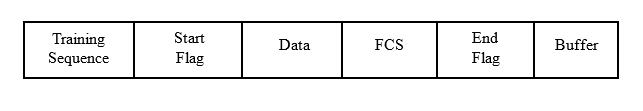

## Receiver Structure

This block diagram shows the receiver code structure. The processing has three main parts: signal source, physical layer and data viewer.

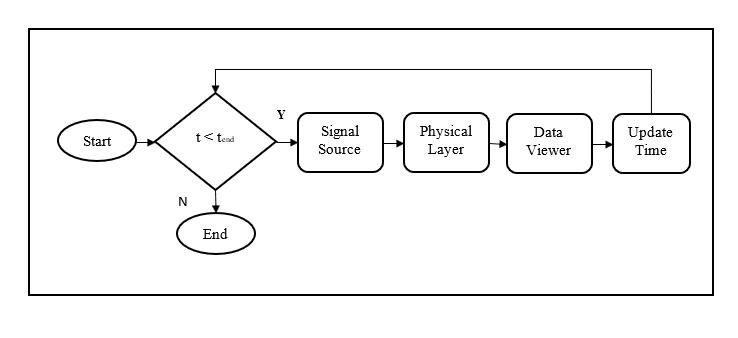

**Signal Source**

Specify the signal source as one of these values

- ''`File`'' — Uses the [Baseband File Reader](docid:comm_ref#bvbbo5v-1) object to read a file that contains a captured signal.

- ''`RTL-SDR`'' — Uses an RTL-SDR radio to receive a live signal. 

- ''`ADALM-PLUTO`'' — Uses a Pluto radio to receive a live signal.

- ''`USRP`'' — Uses a USRP radio to receive a live signal.

The example uses a signal symbol rate of 9600 Hz and 24 samples per symbol.

If you specify ''`RTL-SDR`'' as the signal source, the example searches your computer for an RTL-SDR radio at the radio address '`0`' and uses that radio as the signal source.

If you specify ''`ADALM-PLUTO`'' as the signal source, the example searches your computer for a Pluto radio at the radio address '`usb:0`' and uses that radio as the signal source.

If you specify ''`USRP`'' as the signal source, the example searches your computer for a USRP radio at the radio address you specify and uses that radio as the signal source.

**Physical Layer**

The physical layer (PHY) processes the baseband samples from the signal source to produce packets that contain the ship position information and raw message bytes. This figure shows the PHY processing components.

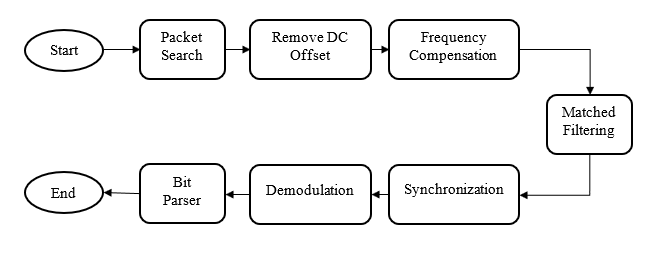

- Packet Search — Search for the strongest burst in the received signal by dividing into multiple windows.

- DC Offset Removal — Remove DC offset from the detected signal.

- Frequency Compensation — Estimate and compensate for the carrier frequency offset.

- Matched Filtering — Perform filtering with a Gaussian pulse generated according to AIS specifications.

- Synchronization and Demodulation — Perform timing synchronization by correlating the received signal with the known preamble and demodulate to produce bits.

- AIS Bit Parser — Detect the Start Flag and End Flags, then perform CRC detection. If the CRC is successful, then decodes the ship information.

AIS signal contains 64 specific message types. Ship position information is included in 11 of the message types. In this example, you decode all of the 11 message types that contain ship position information.

This example lists the ship position information including the ship ID, latitude, and longitude, as well as the associated date and time in a table. For decoding additional information from the messages, see [1].

**Data Viewer**

The data viewer shows the received messages on a graphical user interface (GUI). As data is captured, the application lists information that it decodes from these messages in a table.

## Track Ships Using AIS Signals

The default configuration runs for a duration of 10 seconds and uses signal data from a captured data file, and outputs to a text file. To provide input values from the command line, you must change `cmdlineInput` to 1, then you will be prompted to enter the following information when you run the example:

- Reception duration in seconds,

- Signal source (Captured data file or RTL-SDR radio or ADALM-PLUTO radio or USRP radio),

- Optional output methods (map, text file, or both).

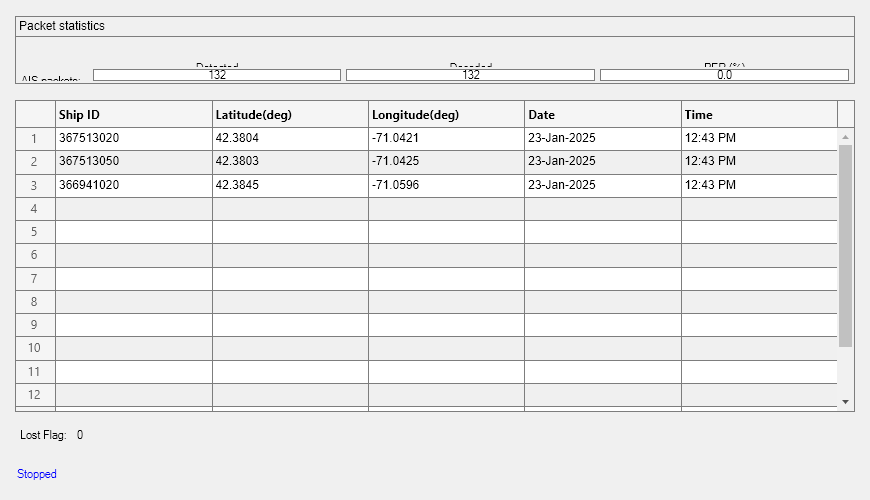

cmdlineInput = 0;
if cmdlineInput
    % Request user input from the command-line for application parameters
    userInput = helperAISUserInput;
else
    load('defaultInputs.mat');
end
% Calculate AIS parameters based on the user input
[aisParam,sigSrc] = helperAISConfig(userInput);

% Create the data viewer object and configure based on user input
viewer = helperAISViewer('LogFileName',userInput.LogFilename, ...
                         'SignalSourceType',userInput.SignalSourceType);

% Launch map based on user input
if userInput.LaunchMap
    startMapUpdate(viewer);
end

% Log data based on user input
if userInput.LogData
    startDataLog(viewer);
end

% Start the viewer and initialize radio time
start(viewer)
radioTime = 0;

% Main loop for capturing and decoding the AIS samples
while radioTime < userInput.Duration  
    if aisParam.isSourceRadio       
        if aisParam.isSourceRTLSDRRadio         % For RTL-SDR
            [rcv,~,lost,~] = sigSrc();
            lostFlag = logical(lost);         
        elseif aisParam.isSourcePlutoSDRRadio   % For ADALM-PLUTO
            [rcv,~,lostFlag] = sigSrc();
        elseif aisParam.isSourceUSRPRadio       % For USRP
            [rcv,~,lostFlag] = sigSrc(); 
        end
    else                                        % For baseband file
        rcv = sigSrc();
        lostFlag = uint32(0);
    end

    % Recover the information by decoding AIS samples
    [info, pkt] = helperAISRxPhy(rcv,aisParam);

    % View decoded information on viewer
    update(viewer, info, pkt, lostFlag);

    % Update radio time
    radioTime = radioTime + aisParam.FrameDuration;
end

% Stop the viewer and release the signal source
stop(viewer)

release(sigSrc)

If you have the Mapping Toolbox, you can also observe AIS tracking of ships on a map.

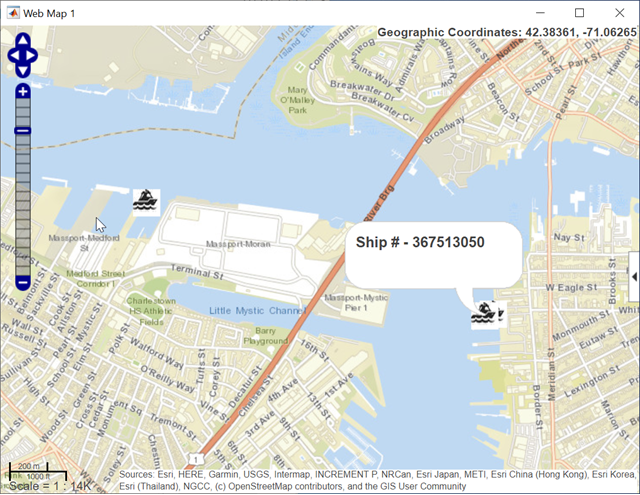

## Further Exploration

You can investigate AIS signals using the  [AISExampleApp](matlab:commandwindow;AISExampleApp). To launch the app, enter `AISExampleApp` in the MATLAB® Command Window. Use the app interface to select the signal source and change the duration.

You can explore the supporting functions and System objects for details of the physical layer implementation.

- [helperAISRxPhy.m](matlab:openExample('comm/ShipTrackingUsingAISSignalsExample','supportingFile','helperAISRxPhy.m'))

- [helperAISRxPhyPacketSearch.m](matlab:openExample('comm/ShipTrackingUsingAISSignalsExample','supportingFile','helperAISRxPhyPacketSearch.m'))

- [helperAISRxPhyFreqComp.m](matlab:openExample('comm/ShipTrackingUsingAISSignalsExample','supportingFile','helperAISRxPhyFreqComp.m'))

- [helperAISRxPhySyncDemod.m](matlab:openExample('comm/ShipTrackingUsingAISSignalsExample','supportingFile','helperAISRxPhySyncDemod.m'))

- [helperAISRxPhyBitParser.m](matlab:openExample('comm/ShipTrackingUsingAISSignalsExample','supportingFile','helperAISRxPhyBitParser.m'))

## References

[1] Recommendation ITU-R M.1371-5. "Technical characteristics for an automatic identification system using time division multiple access in the VHF maritime mobile frequency band",* International Telecommunication Union. *[https://www.itu.int/rec/R-REC-M.1371-5-201402-I/en](https://www.itu.int/rec/R-REC-M.1371-5-201402-I/en)

*Copyright 2020-2024 The MathWorks, Inc.*